# Identifying and Designing Neural Networks

This example shows how to use MATLAB and the Deep Network Designer app to build deep learning solutions to two different problems:

- Diabetes prediction

- Medical image classification.

## Part 1: Diabetes prediction

### **Problem**

Given (tabular) anonymized health data about the incidence of a diabetes in a given population, design a binary classifier to predict whether an individual with certain health indicators is likely to develop diabetes or not.

### **Dataset**

We will use the [Kaggle's version of the Pima Indians diabetes database](https://www.kaggle.com/uciml/pima-indians-diabetes-database)

*This dataset is originally from the National Institute of Diabetes and Digestive and Kidney Diseases. The objective of the dataset is to diagnostically predict whether or not a patient has diabetes, based on certain diagnostic measurements included in the dataset. Several constraints were placed on the selection of these instances from a larger database. In particular, all patients here are females at least 21 years old of Pima Indian heritage.*

The dataset consists of several medical predictor variables (such as age, BMI, insulin level, and number of pregnancies) and one target variable, `Outcome`. 

See [https://www.ncbi.nlm.nih.gov/pmc/articles/PMC7270283/](https://www.ncbi.nlm.nih.gov/pmc/articles/PMC7270283/) for an example of a recent scientific article using this dataset.

### Solution

We will build a fully connected feedforward neural network from scracth using the Deep Network Designer app and test the resulting model to determine its accuracy.

### Procedure

- Read the data.

- Clean up and prepare the data.

- Split the data into training, validation, and test sets.

- Design the network architecture using Deep Network Designer app and save the resulting model.

- Define training options.

- Train the model.

- Use the model to make predictions.

- Compute accuracy on test set.

#### Read the data 

opts = detectImportOptions('diabetes.csv');
preview('diabetes.csv',opts)

ans = 8×9 table
    Pregnancies    Glucose    BloodPressure    SkinThickness    Insulin    BMI     DiabetesPedigreeFunction    Age    Outcome
    ___________    _______    _____________    _____________    _______    ____    ________________________    ___    _______

         6           148           72               35              0      33.6             0.627              50        1   
         1            85           66               29              0      26.6             0.351              31        0   
         8           183           64                0              0      23.3             0.672              32        1   
         1            89           66          

data = readtable('diabetes.csv', 'Format','auto');

#### Clean up and prepare the data

Useful link: [https://www.mathworks.com/help/deeplearning/ref/trainnetwork.html](https://www.mathworks.com/help/deeplearning/ref/trainnetwork.html) 

Convert the labels for prediction to categorical using the `convertvars` function.

labelName = "Outcome";
data = convertvars(data,labelName,'categorical');

Split table into `predictors` (8 first columns) and `trueLabel` (right-most column).

predictors = data(:,1:end-1);
trueLabels = data(:,'Outcome');
numObservations = size(predictors,1);
numFeatures = size(predictors,2);
classNames = categories(data{:,labelName});
numClasses = numel(classNames);

Compute baseline accuracy based on the dataset distribution. 

(Note that *the dataset is unbalanced* which means that the baseline accuracy against which you might want to compare your solution is **not** 50%. 

summary = groupsummary(data,'Outcome');
classZero = summary{1,2};
classOne = summary{2,2};
baselineAccuracy = classZero/(classZero + classOne)

baselineAccuracy = 0.6510

#### Split the data into training, validation, and test sets

We choose to use 70% of the records for training, 15% for validation, and leave the remaining 15% for testing. 

rng('default');
numObservationsTrain = floor(0.7*numObservations);
numObservationsValidation = floor(0.15*numObservations);

idx = randperm(numObservations);
idxTrain = idx(1:numObservationsTrain);
idxValidation = idx(numObservationsTrain + 1:numObservationsTrain + numObservationsValidation);
idxTest = idx(numObservationsTrain + numObservationsValidation + 1:end);

dataTrain = data(idxTrain,:);
dataVal = data(idxValidation,:);
dataTest = data(idxTest,:);

#### Design the network architecture (using Deep Network Designer app)

In this step we can use the Deep Network Designer app to build our network by dragging, dropping, connecting, and configuring each layer interactively. 

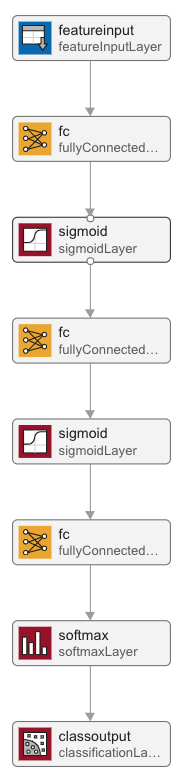

The resulting network can then be exported to MATLAB workspace as a variable whose contents are shown below.

net1_layers = [
    featureInputLayer(8,"Name","featureinput","Normalization","rescale-symmetric")
    fullyConnectedLayer(128,"Name","fc_1")
    sigmoidLayer("Name","sigmoid_1")
    fullyConnectedLayer(128,"Name","fc_3")
    sigmoidLayer("Name","sigmoid_2")
    fullyConnectedLayer(2,"Name","fc_2")
    softmaxLayer("Name","softmax")
    classificationLayer("Name","classoutput")];

#### Define training options 

We can define the training options interactively (using the Deep Network Designer app) or programmatically, as follows:

miniBatchSize = 15;
opts = trainingOptions('adam', ...
    'MaxEpochs',100, ...
    'MiniBatchSize',miniBatchSize, ...
    'Shuffle','every-epoch', ...
    'Plots','training-progress', ...
    'ValidationData',dataVal, ...
    'OutputNetwork','best-validation-loss',...
    'ValidationPatience', 5, ...
    'Verbose',false);

#### Train network

It's time to train our network.

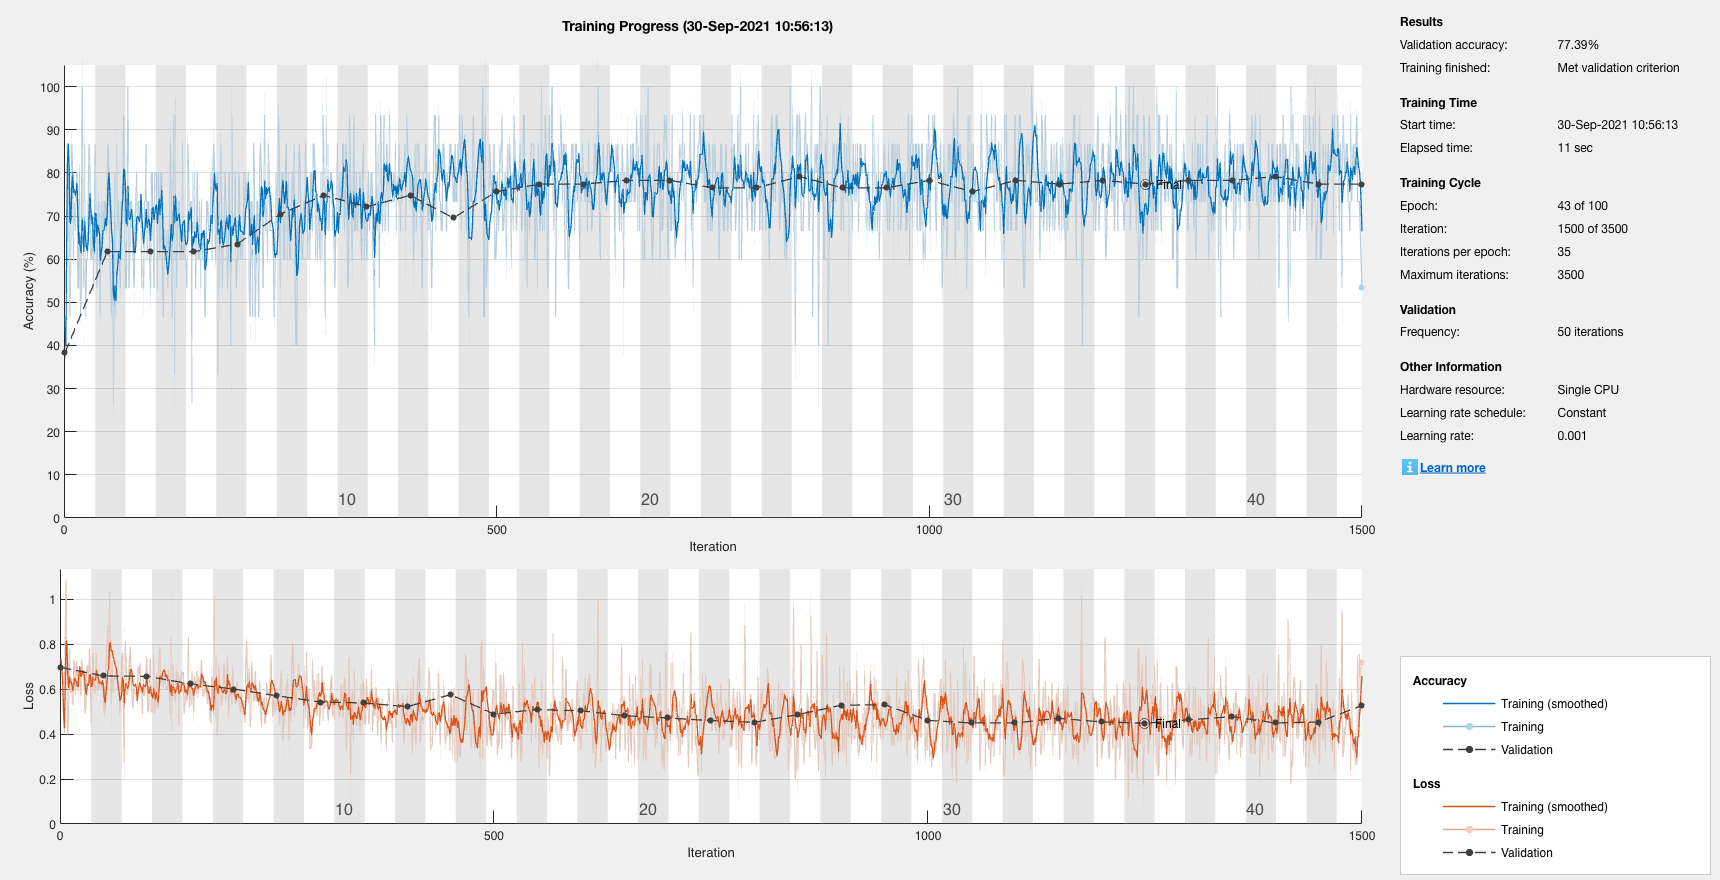

net1 = trainNetwork(dataTrain,net1_layers,opts);

#### Use model to make predictions

We can now use the resulting model to make predictions on the test dataset.

YPred = classify(net1,dataTest,'MiniBatchSize',miniBatchSize);
YTest = dataTest{:,labelName};

#### Compute accuracy on test set

It's time to compute the accuracy and see how well we did.

accuracy = sum(YPred == YTest)/numel(YTest)

accuracy = 0.7241

### Summary

- We created a relatively small neural network to solve a **binary classification** problem using **tabular data**.

- The model achieved an **accuracy **slighly higher than 70% on the test set, which is **better than the baseline**, but not by much.

- **There is a lot of room for improvement! **We could perform **feature selection** (and maybe discard features that are not likely to help the prediction), tweak the **architecure** (e.g., adding more layers and/or more neurons per layer), experiment with **different activation functions**, try **different training options** (optimizer, learning rate, etc.), among many other things.

## Part 2: Medical image modality classification

### Problem

Given a collection of medical images from 6 different modalities, design a multiclass classifier to label a previously unseen image according to the category (modality) to which it should belong.

### **Dataset**

The MedNIST dataset was created for educational purposes and contains medical images gathered from several sets from [TCIA](https://wiki.cancerimagingarchive.net/display/Public/Data+Usage+Policies+and+Restrictions), [the RSNA Bone Age Challenge](http://rsnachallenges.cloudapp.net/competitions/4), and [the NIH Chest X-ray dataset](https://cloud.google.com/healthcare/docs/resources/public-datasets/nih-chest). The name MedNIST was inspired by the popular MNIST dataset, which has been called "the 'Hello World' of deep learning." The main difference is that, instead of containing images of handwritten digits, MedNIST contains medical images.

There are 6 folders in the dataset: Hand, AbdomenCT, CXR, ChestCT, BreastMRI, HeadCT, whose names should be used as the *labels* to train our classification model.

The dataset is kindly made available by [Dr. Bradley J. Erickson M.D., Ph.D.](https://www.mayo.edu/research/labs/radiology-informatics/overview) (Department of Radiology, Mayo Clinic) under the Creative Commons [CC BY-SA 4.0 license](https://creativecommons.org/licenses/by-sa/4.0/). If you use the MedNIST dataset, please acknowledge the source, e.g. 

[https://github.com/Project-MONAI/MONAI/blob/master/examples/notebooks/mednist_tutorial.ipynb](https://github.com/Project-MONAI/MONAI/blob/master/examples/notebooks/mednist_tutorial.ipynb) 

### Solution

In this part we build an image classifier starting from a pre-trained (on ImageNet) CNN under the *transfer learning* paradigm. Once again, we use the Deep Network Designer app to build our solution by [following these steps](https://www.mathworks.com/help/deeplearning/gs/get-started-with-deep-network-designer.html):

- Open the Deep Network Designer app and choose a pretrained network.

- Import the new data set.

- Replace the final layers with new layers adapted to the new data set.

- Set learning rates so that learning is faster in the new layers than in the transferred layers.

- Train the network using Deep Network Designer, or export the network for training at the command line.

### Procedure

- Read the data.

- Clean up and prepare the data.

- Split the data into training and validation sets.

- Perform data augmentation.

- Design a convolutional neural network (CNN) using Deep Network Designer app and save the resulting model.

- Define training options.

- Train the model.

- Use the model to make predictions.

- Compute accuracy on test set.

#### Read the data 

Download the MedNIST.tar.gz file available [here](https://www.dropbox.com/s/5wwskxctvcxiuea/MedNIST.tar.gz). 

Once you open the file and expand it, it should produce a folder structure where each folder is named with the image category.

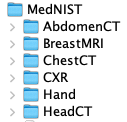

#### Clean up and prepare the data

Create image datastore.

imageDS = datastore(fullfile('./MedNIST/'), ...
    "IncludeSubfolders", true, "FileExtensions", ".jpeg", "Type", "image", ...
    "LabelSource", "foldernames");

#### Split the data into training, validation, and test sets

[MedNISTtrain, MedNISTval, MedNISTtest] = splitEachLabel(imageDS, 0.8, 0.1, 'randomized');

#### Data augmentation

We use [`augmentedImageDatastore`](https://www.mathworks.com/help/deeplearning/ref/augmentedimagedatastore.html) to elegantly handle image data augmentation (for training) as well as color processing and resizing tasks (for all data sets) and take advantage of the functionality under the **Data** tab to import and inspect the data.  

imageAugmenter = imageDataAugmenter( ...
    'RandRotation',[-20,20], ...
    'RandXTranslation',[-3 3], ...
    'RandYTranslation',[-3 3]);

imageSize = [227 227 1];
augimdsTrain = augmentedImageDatastore(imageSize,MedNISTtrain,'DataAugmentation',imageAugmenter, 'ColorPreprocessing','gray2rgb');
augimdsVal = augmentedImageDatastore(imageSize,MedNISTval,'ColorPreprocessing','gray2rgb');
augimdsTest = augmentedImageDatastore(imageSize,MedNISTtest,'ColorPreprocessing','gray2rgb');

#### Design and train network

Open Deep Network Designer app and follow these instructions (adapted from [this](https://www.mathworks.com/help/deeplearning/gs/get-started-with-deep-network-designer.html) MathWorks page):

1. Select **SqueezeNet** from the list of pretrained networks and click **Open**.

2.** Import data**

Load the data into Deep Network Designer. On the **Data** tab, click **Import Data** > **Import Image Data**. The Import Image Data dialog box opens. In the **Data source** list, select Workspace and choose `augimdsTrain` and `augimdsVal` for the training and validation set, respectively.

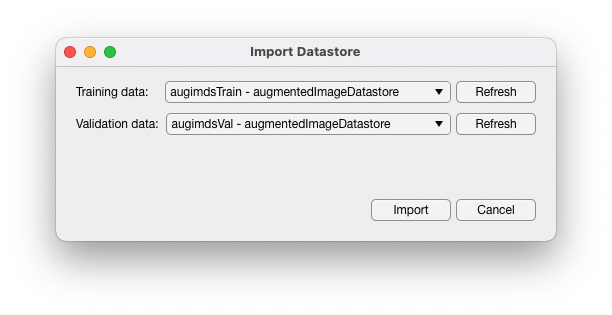

3. **Visualize data**

Using Deep Network Designer, you can visually inspect the distribution of the training and validation data in the **Data** tab. You can see that, in this example, there are six classes in the data set. You can also see random observations from each class.

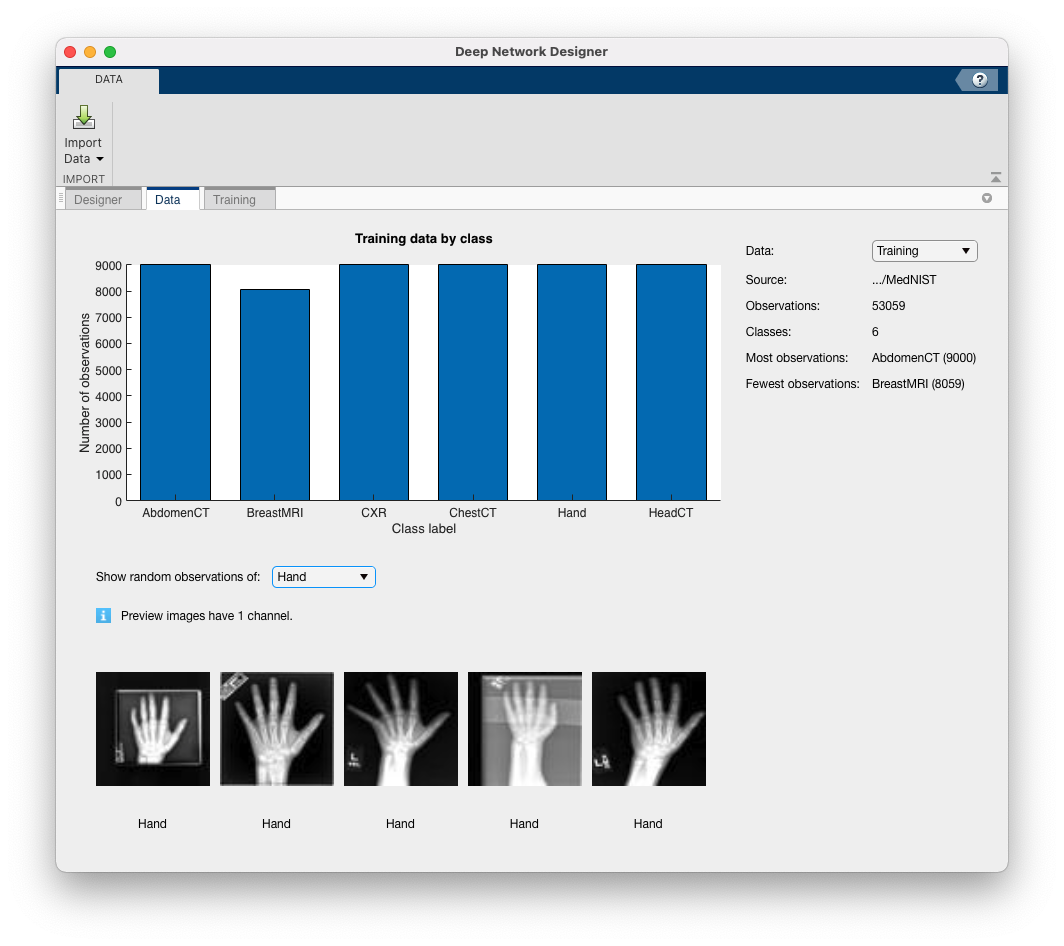

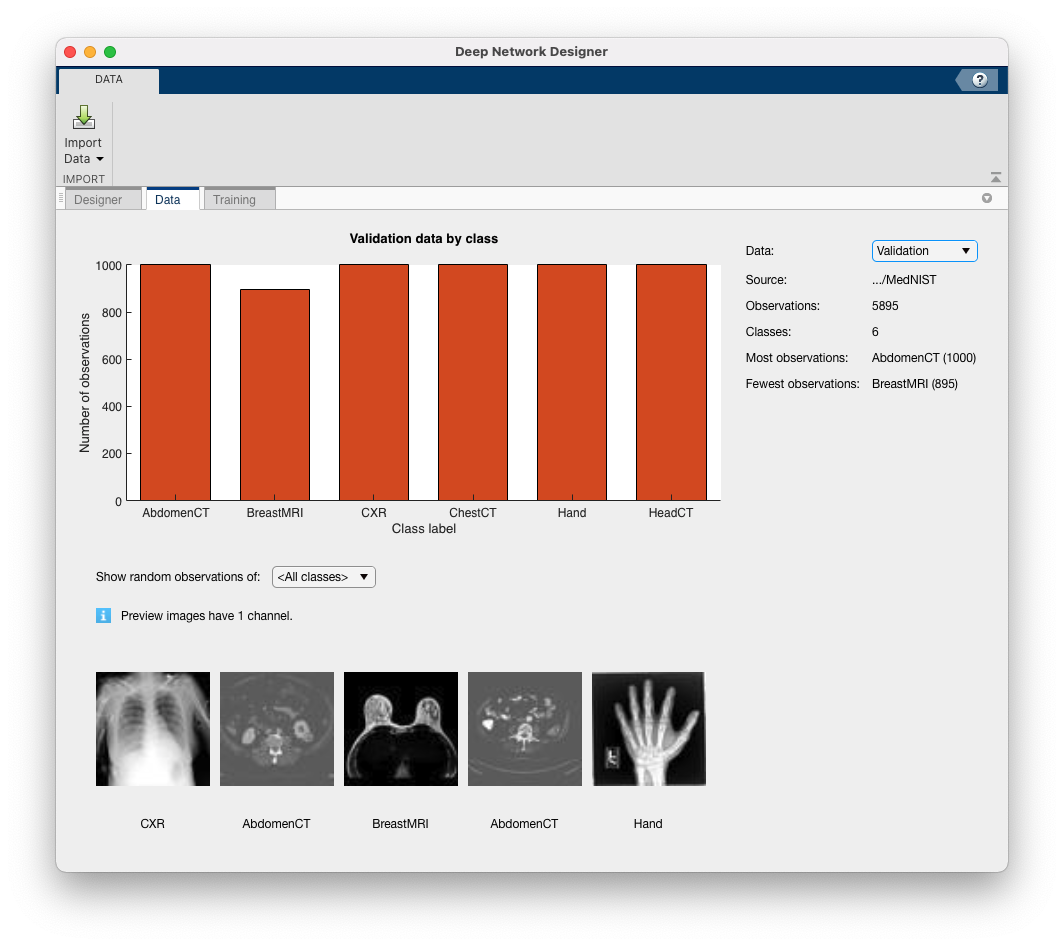

4. **Prepare Network for Training**

There are two main steps here: replace the last learnable layer and the final classification layer. Let's look ath the details behind each step.

**Replace Last Learnable Layer**

To use a pretrained network for transfer learning, we must change the number of classes to match our new data set. 

First, we must find the last learnable layer in the network. For SqueezeNet, the last learnable layer is the last convolutional layer, 'conv10'. In this case, we replace the convolutional layer with a new convolutional layer with the number of filters equal to the number of classes by dragging a new `convolution2dLayer` block onto the canvas. To match the original convolutional layer, we set `FilterSize` to 1,1. The `NumFilters` property should also be edited to reflect the number of classes in the new data, in this example, 6. We should also change the learning rates so that learning is faster in the new layer than in the transferred layers by setting both `WeightLearnRateFactor` and `BiasLearnRateFactor` to 10. Once we are done configuring the new block/layer, we can delete the last 2-D convolutional layer and connect our new layer instead.

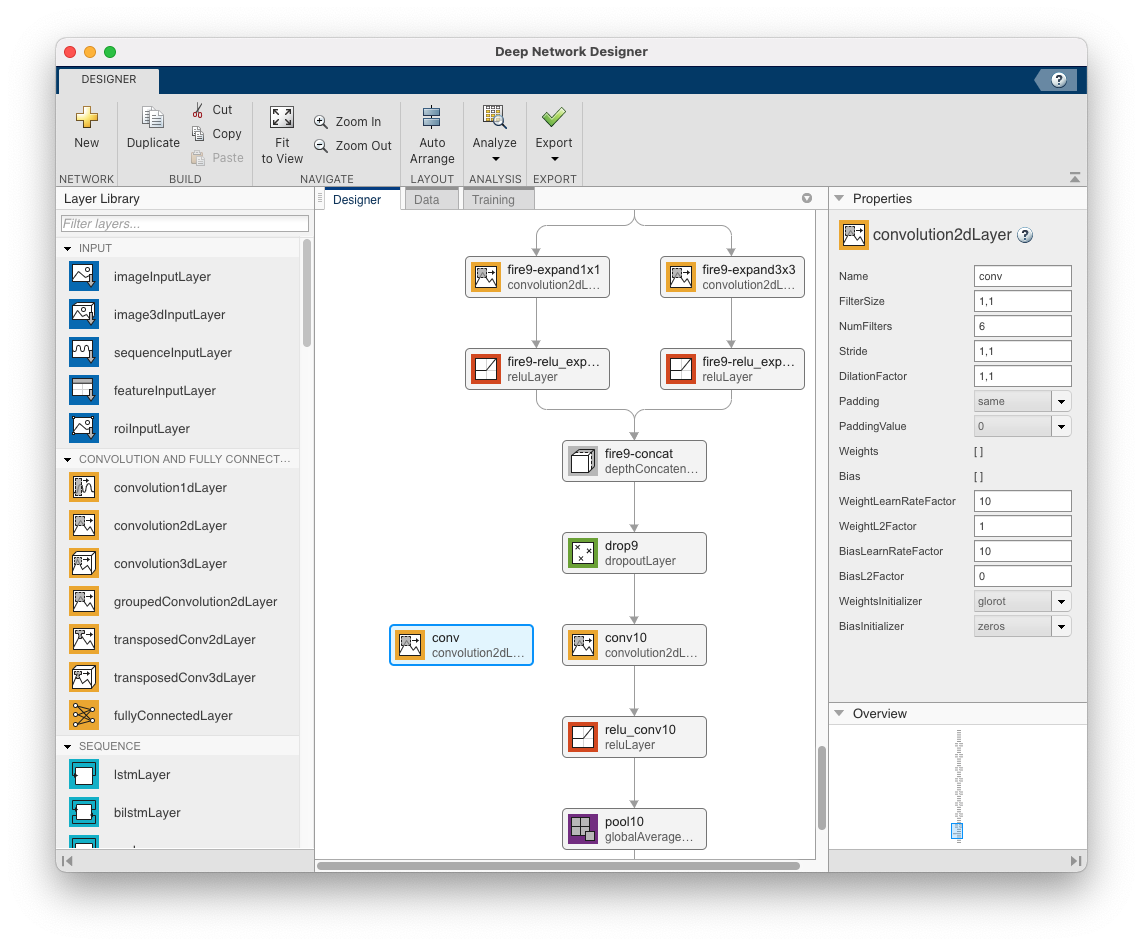

**Replace Output Layer**

For transfer learning, we need to replace the output layer by scrolling to the end of the **Layer Library**, dragging  a new `classificationLayer` onto the canvas, deleting the original classification layer and connecting our new layer in its place. There is no need to set the `OutputSize` for the new output layer. At training time, Deep Network Designer automatically sets the output classes of the layer from the data.

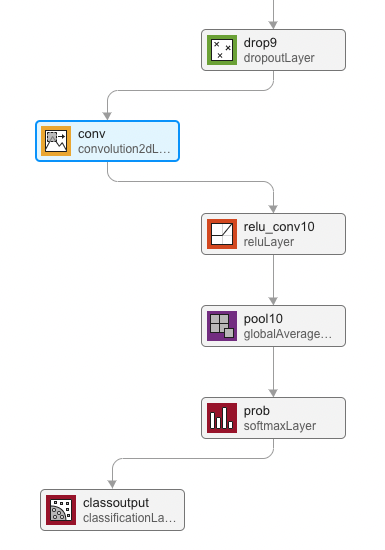

**Check Network**

To check that the network is ready for training, click **Analyze**. If the Deep Learning Network Analyzer reports zero errors, then the edited network is ready for training.

**Export Network**

Export the resulting network to a [Live Script file](matlab:open('./Part2.mlx')). 

#### Train network

Run that script to train the network. 

**Note**: this is a potentially time-consuming step, depending on your (CPU/GPU) setup.

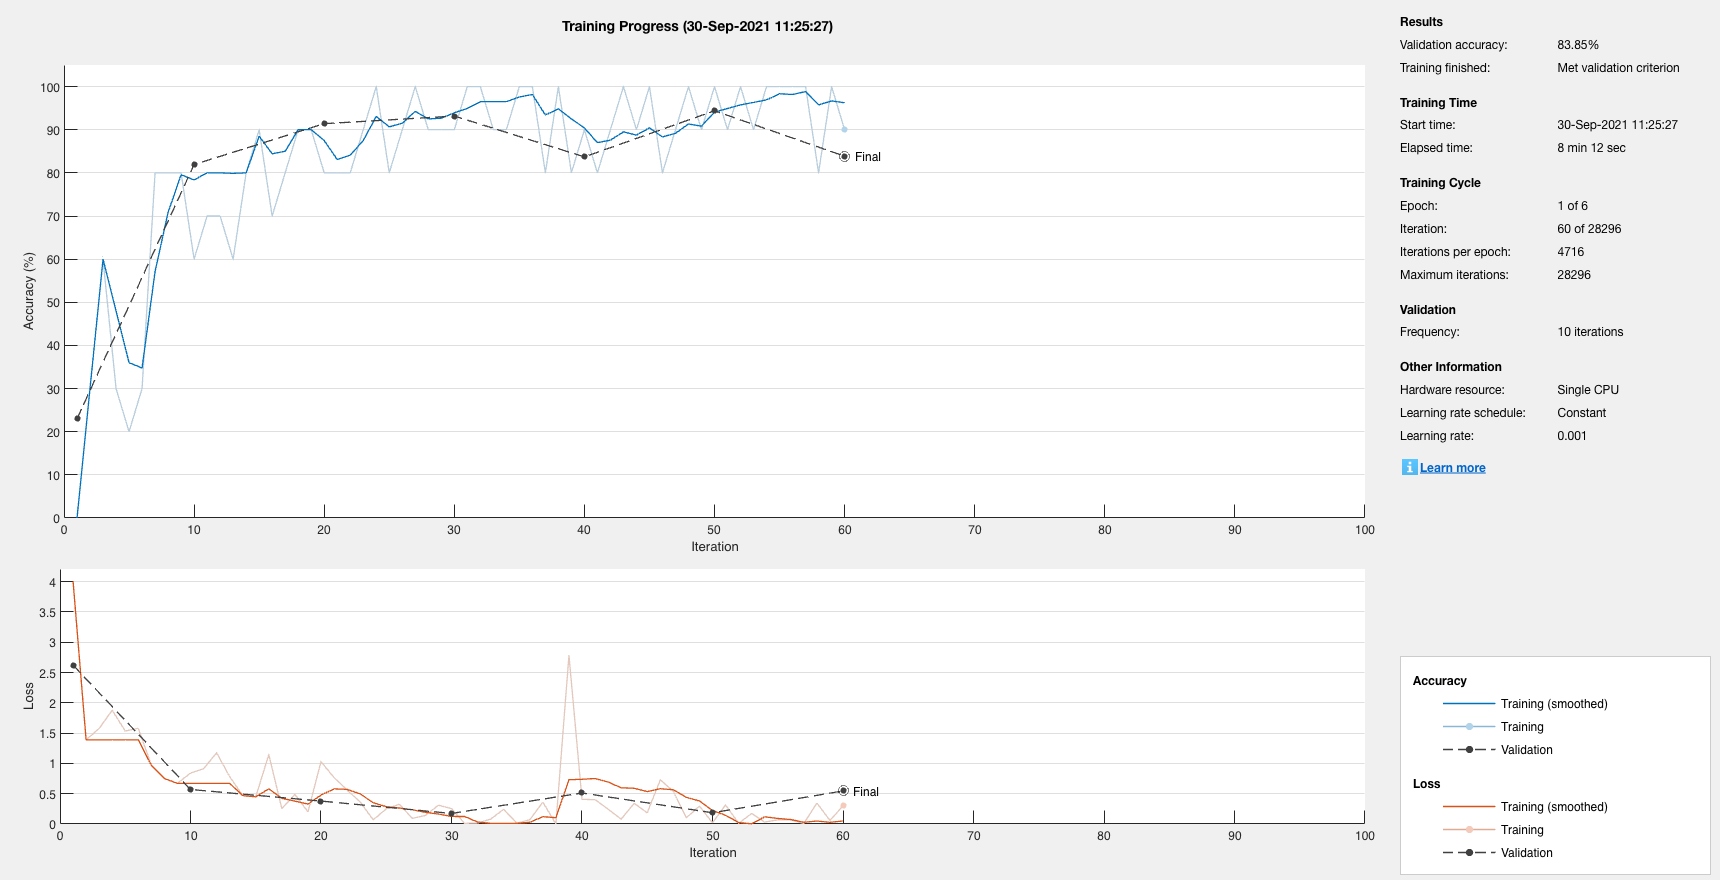

Part2

#### Use the model to make predictions

[YPred,scores] = classify(net2,augimdsTest);

#### Compute accuracy on test set

YTest = MedNISTtest.Labels;
accuracy = mean(YPred == YTest)

accuracy = 0.8451

### Summary

- We adopted a **transfer learning** approach to reuse a pretrained neural network (SqueezeNet) to solve a multiclass** image classification** problem.

- The model achieved an **accuracy **slighly higher than 80% on the test set, which is **significantly** **better than the baseline**.

- **There is always room for improvement! **We could select different pretrained models, change the training/validation split percentages, experiment with  **different training options** (optimizer, learning rate, etc.), among many other things.